## T4: Fourier transform

## Stationary signal

System parameters

clear
clc
close all

Fs = 1000;       % Sampling frequency [Hz]
T = 1/Fs;        % Sampling time step [s]
s = 2;           % Signal length [s]
L = s*Fs;        % Signal length (number of samples)
t = (0:L-1)*T;   % Time base
f = 0:1/s:Fs/2;  % Frequency base

Signal creation

N = 3;               % Number of signals
Amp = [1.0   0.4  0.8] % Amplitude

Amp =     1.0000    0.4000    0.8000


B = [ 15    27   83] % Frequency [Hz]

B =     15    27    83


C = [  0 -pi/3 pi/7] % Phase shift

C =          0   -1.0472    0.4488



% simple way
x = zeros(size(t));
for i = 1:N
  x = x + Amp(i) * cos(2 * pi * B(i) * t + C(i));
end

## Fast Fourier Transform

Y = fft(x);     % Fast Fourier Transform

A = abs(Y);     % Amplitude
A = A/L;        % Amplitude normalization
A = A(1:L/2+1); % Cut important part 
A(2:end-1) = 2*A(2:end-1);

P = angle(Y);   % Phase
P = P(1:L/2+1); % Cut important part


Plots

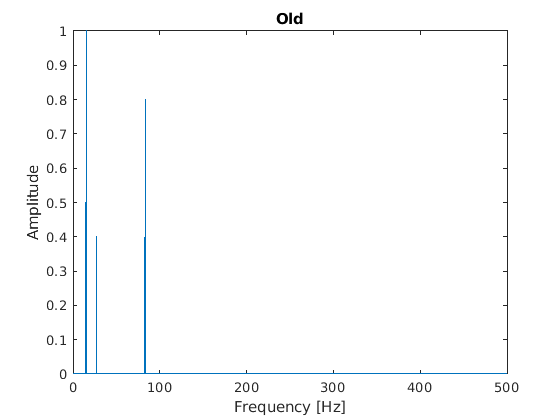

figure;
plot(f, A);
title('Old')
xlabel("Frequency [Hz]");
ylabel("Amplitude");

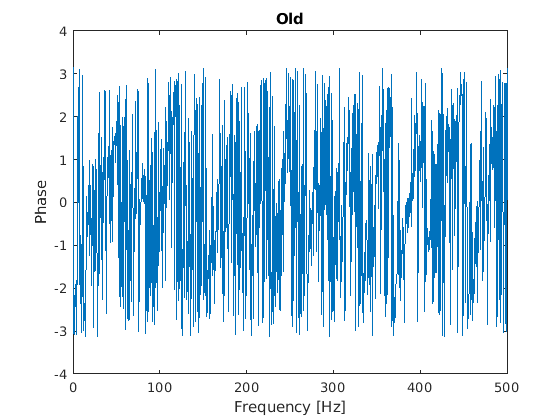

figure;
plot(f, P);
title('Old')
xlabel("Frequency [Hz]");
ylabel("Phase");

## Noisy signals

n=2*randn(1,length(x)); % Random noise 

xnew=x+n;   % New noisy signal

Ynew = fft(xnew);     % New Fast Fourier Transform

Anew = abs(Ynew);     % New Amplitude
Anew = Anew/L;        % Amplitude normalization
Anew = Anew(1:L/2+1); % Cut important part 
Anew(2:end-1) = 2*Anew(2:end-1);

Pnew = angle(Ynew);   % New Phase
Pnew = Pnew(1:L/2+1); % Cut important part

Plots

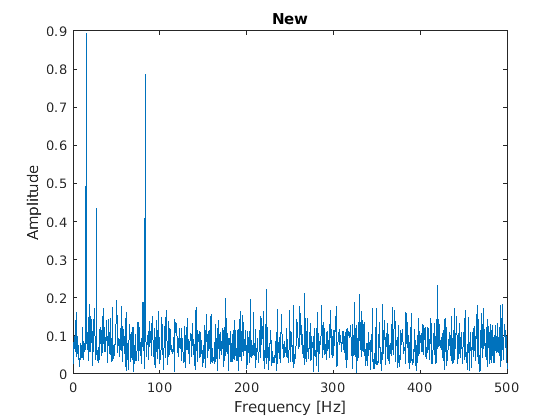

figure;
plot(f, Anew);
title('New')
xlabel("Frequency [Hz]");
ylabel("Amplitude");

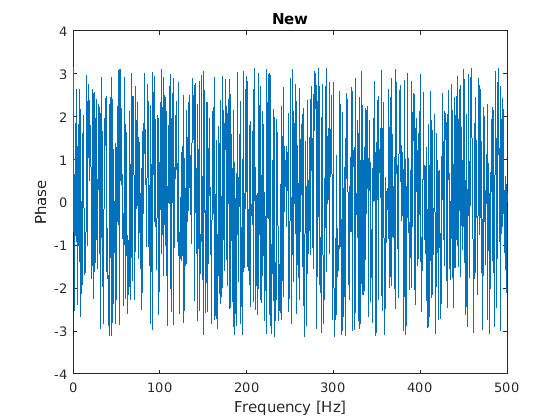

figure;
plot(f, Pnew);
title('New')
xlabel("Frequency [Hz]");
ylabel("Phase");

Three dominant amplitudes and corresponding frequencies and phase shifts

domAmp=maxk(Anew,3);    % Three dominant amplitudes 

% Corresponding frequencies
domFreq=zeros(size(3)); 

for i=1:3
    dom = find(Anew == domAmp(i));
    domFreq(i) = f(dom);
end

% Corresponding phase shifts
domPhase=zeros(size(3));

for i=1:3
    dom = find(f == domFreq(i));
    domPhase(i) = Pnew(dom);
end

% Sort matrices based on Frequency
[domFreqsorted,I]=sort(domFreq);

A1=domAmp(I)

A1 =     0.8941    0.4336    0.7870


B1=domFreq(I)

B1 =     15    27    83


C1=domPhase(I)

C1 =    -0.0101   -0.8660    0.4107


Reconstruct the initial signal

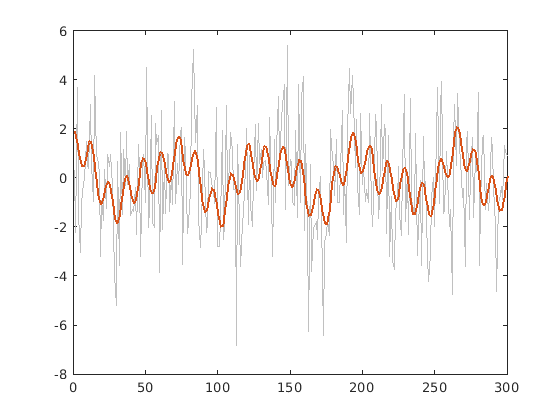

x1 = sum(A1' .* cos(2 * pi * B1' * t + C1'));

figure
plot(xnew,'Color' , '#C0C0C0')
hold on
plot(x1,'LineWidth',2)
xlim([0 300])
hold off

Compare the retrieved values

differenceA=Amp-A1  % Difference in amplitude with the original value

differenceA =     0.1059   -0.0336    0.0130


differenceB=B-B1    % Difference in frequency with the original value

differenceB =      0     0     0


differenceC=C-C1    % Difference in phase with the original value

differenceC =     0.0101   -0.1812    0.0381


When comparing the frequency, amplitude, and phase values with with the original ones, the frequency was almost accurate most of the time having a difference of 0.  While the other values change. 

But when comparing by changing the value of the noise it is almost recoverable until mean of 0 and standard deviation of 3. But further increasing the standard deviation the signal starts getting unrecoverable. Difference in frequency will start after this point.